# Dimensionality Reduction by Batch LSUN

## Preparation

clc, clear
close all

## Loading Input Signal

Datasetfolder ='./Experience1/Dataset';
files = dir(fullfile(Datasetfolder,'*.mat'));
data = load(fullfile(Datasetfolder,files(1).name));
u = single(data.u);

if canUseGPU
    disp("Use GPU")
    u = gpuArray(u);
end

Use GPU


[szy,szx,szt] = size(u);

## LSUN Parameter Setting

Block Size (Stride) 

pt = 2;
blksz = [2*pt 2*pt];  % Block size (Stride (even) )
% assert(mod(nX,stride)==0,'stride must be a divisor of nX.'); 

Dimension (Number of Channnels per Block) 

nCoefs = 2; 
% assert(nCoefs<=stride,'nCoefs must be less than or equal to stride.')

Overlapping (Number of Shifts) 

nof = 1;
kx = 2*nof+1; % Number of Overlapping (odd)
ky = 2*nof+1;

### Display of Each Value

strbuf = "-- Setting --" + newline;
strbuf = strbuf.append("Datasize (spatial) X Y: " + num2str([szx szy]) + newline);
strbuf = strbuf.append("Datasize（temporal）T: " + num2str(szt) + newline);
strbuf = strbuf.append("Block size: " + num2str(blksz) + newline);
strbuf = strbuf.append("Output dimention (per block): " + num2str(nCoefs) + newline);
strbuf = strbuf.append("Number of overlap: " + num2str([kx ky]) + newline);
disp(strbuf)

## Training Setting

%% Decimation factor

-- Setting --
Datasize (spatial) X Y: 300  300
Datasize（temporal）T: 150
Block size: 4  4
Output dimention (per block): 1
Number of overlap: 3  3



stride = blksz; % [My Mx]

%% Number of overlapping blocks (Polyphase order plus one)
ovlpFactor = [ky kx];

%% Max epochs
maxEpochs = 1200;

%% Standard deviation of initial angles
stdInitAng = 0;

%% No DC-leakage
noDcLeakage = true; % logical 1

## Bivariate lattice-structure of filter banks 

As a base system for LSUN, let us adopt a multidimensional linear-phase paraunitary filter banks (MD-LPPUFB) ( or non-separable oversampled lapped transform (NSOLT)) of  type-I with the number of channels (the numbers of even and odd symmetric channels are identical to each other) and polyphase order (even):

        
$$\mathbf{E}(z_\mathrm{v},z_\mathbf{h})
=
\left(\prod_{k_\mathrm{h}=1}^{N_\mathrm{h}/2}
{\mathbf{V}_{2k_\mathrm{h}}^{\{\mathrm{h}\}}}\bar{\mathbf{Q}}(z_\mathrm{h}){\mathbf{V}_{2k_\mathrm{h}-1}^{\{\mathrm{h}\}}}{\mathbf{Q}}(z_\mathrm{h})\right)
%
\left(\prod_{k_{\mathrm{v}}=1}^{N_\mathrm{v}/2}{\mathbf{V}_{2k_\mathrm{v}}^{\{\mathrm{v}\}}}\bar{\mathbf{Q}}(z_\mathrm{v}){\mathbf{V}_{2k_\mathrm{v}-1}^{\{\mathrm{v}\}}}{\mathbf{Q}}(z_\mathrm{v})\right)
%
\mathbf{V}_0\mathbf{E}_0,$$


        
$$\mathbf{R}(z_\mathrm{v},z_\mathbf{h})
=\mathbf{E}^T(z_\mathrm{v}^{-1},z_\mathrm{h}^{-1}),$$


where

- $\mathbf{E}(z_\mathrm{v},z_\mathrm{h})$:  Type-I polyphase matrix of the analysis filter bank

- $\mathbf{R}(z_\mathrm{v},z_\mathrm{h})$: Type-II polyphase matrix in the synthesis filter bank

- $z_d\in\mathbb{C}, d\in\{\mathrm{v},\mathrm{h}\}$: The parameter of Z-transformation direction

- $N_d\in \mathbb{N}, d\in\{\mathrm{v},\mathrm{h}\}$: Polyphase order in direction $d$ (number of overlapping blocks)

- $\mathbf{V}_0=\left(\begin{array}{cc}\mathbf{W}_{0} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_0\end{array}\right)
%
\left(\begin{array}{c}\mathbf{I}_{M/2} \\ 
\mathbf{O} \\
\mathbf{I}_{M/2} \\
\mathbf{O}
\end{array}\right)\in\mathbb{R}^{P\times M}$,$\mathbf{V}_n^{\{d\}}=\left(\begin{array}{cc}\mathbf{I}_{P/2} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_n^{\{d\}}\end{array}\right)\in\mathbb{R}^{P\times P}, d\in\{\mathrm{v},\mathrm{h}\}$, where$\mathbf{W}_0, \mathbf{U}_0,\mathbf{U}_n^{\{d\}}\in\mathbb{R}^{P/2\times P/2}$are orthonromal matrices.

- $\mathbf{Q}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  z^{-1}\mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\bar{\mathbf{Q}}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} z\mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  \mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\mathbf{B}_{P}=\frac{1}{\sqrt{2}}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{I}_{P/2} \\ \mathbf{I}_{P/2} &  -\mathbf{I}_{P/2}\end{array}\right)$

【Example】For $P/2=3$, a parametric orthonormal matrix $\mathbf{U}(\mathbf{\theta},\mathbf{\mu})$ can be constructed by 

        
$$\mathbf{U}(\mathbf{\theta},\mathbf{\mu}) \colon = \left(\begin{array}{cc} \mu_1 & 0& 0\\ 0 & \mu_1 & 0 \\ 0 & 0 & \mu_2 \end{array}\right)
%
\left(\begin{array}{ccc} 
 1 & 0 & 0 \\
0 & \cos\theta_2& -\sin\theta_2 \\ 
0 & \sin\theta_2 & \cos\theta_2 
\end{array}\right)
%
\left(\begin{array}{ccc} 
\cos\theta_1& 0 & -\sin\theta_1  \\ 
 0 & 1 & 0 \\
\sin\theta_1 & 0 &  \cos\theta_1 
 \end{array}\right)
%
\left(\begin{array}{ccc} 
\cos\theta_0& -\sin\theta_0 & 0 \\ 
\sin\theta_0 & \cos\theta_0 & 0 \\
 0 & 0 & 1 \end{array}\right),$$


        
$${\mathbf{U}(\mathbf{\theta},\mathbf{\mu})}^T = 
%
\left(\begin{array}{ccc} 
\cos\theta_0& \sin\theta_0 & 0 \\ 
-\sin\theta_0 & \cos\theta_0 & 0 \\
 0 & 0 & 1 \end{array}\right)
%
\left(\begin{array}{ccc} 
\cos\theta_1& 0 & \sin\theta_1  \\ 
 0 & 1 & 0 \\
-\sin\theta_1 & 0 &  \cos\theta_1 
 \end{array}\right)
%
\left(\begin{array}{ccc} 
1 & 0 & 0 \\
0 & \cos\theta_2& \sin\theta_2 \\ 
0 & -\sin\theta_2 & \cos\theta_2 
\end{array}\right)
%
\left(\begin{array}{cc} \mu_0 & 0& 0\\ 0 & \mu_1 & 0 \\ 0 & 0 & \mu_2 \end{array}\right),$$


where $\mathbf{\theta}\in\mathbb{R}^{(P-2)P/8}$ and $\mathbf{\mu}=\{-1,1\}^{P/2}$. For the sake of simplification, the sign parameters $\mu_k$ are fixed to $-1$for $\mathbf{U}_n^{\{d\}}$ witn odd $n$, otherwise they are fixed to $+1$.

Partial differentiation can be, for examle, conducted as

        
$$\frac{\partial}{\partial \theta_1}{\mathbf{U}(\mathbf{\theta},\mathbf{\mu})}^T = 
%
\left(\begin{array}{ccc} 
\cos\theta_0& \sin\theta_0 & 0 \\ 
-\sin\theta_0 & \cos\theta_0 & 0 \\
 0 & 0 & 1 \end{array}\right)
%
\left(\begin{array}{ccc} 
-\sin\theta_1& 0 & \cos\theta_1  \\ 
 0 & 0 & 0 \\
-\cos\theta_1 & 0 &  -\sin\theta_1 
 \end{array}\right)
%
\left(\begin{array}{ccc} 
1 & 0 & 0 \\
0 & \cos\theta_2& \sin\theta_2 \\ 
0 & -\sin\theta_2 & \cos\theta_2 
\end{array}\right)
%
\left(\begin{array}{cc} \mu_0 & 0& 0\\ 0 & \mu_1 & 0 \\ 0 & 0 & \mu_2 \end{array}\right).$$


A locally-structured unitary network (LSUN) allows to change the parameters block by block.

【References】 

- MATLAB SaivDr Package: [https://github.com/msiplab/SaivDr](https://github.com/msiplab/SaivDr)

- S. Muramatsu, K. Furuya and N. Yuki, "Multidimensional Nonseparable Oversampled Lapped Transforms: Theory and Design," in IEEE Transactions on Signal Processing, vol. 65, no. 5, pp. 1251-1264, 1 March1, 2017, [doi: 10.1109/TSP.2016.2633240](https://ieeexplore.ieee.org/document/7762239).

- S. Muramatsu, T. Kobayashi, M. Hiki and H. Kikuchi, "Boundary Operation of 2-D Nonseparable Linear-Phase Paraunitary Filter Banks," in IEEE Transactions on Image Processing, vol. 21, no. 4, pp. 2314-2318, April 2012, doi: 10.1109/TIP.2011.2181527.

- S. Muramatsu, M. Ishii and Z. Chen, "Efficient parameter optimization for example-based design of nonseparable oversampled lapped transform," 2016 IEEE International Conference on Image Processing (ICIP), Phoenix, AZ, 2016, pp. 3618-3622, doi: 10.1109/ICIP.2016.7533034.

- Furuya, K., Hara, S., Seino, K., & Muramatsu, S. (2016). Boundary operation of 2D non-separable oversampled lapped transforms. *APSIPA Transactions on Signal and Information Processing, 5*, E9. doi:10.1017/ATSIP.2016.3.

- S. Muramatsu, A. Yamada and H. Kiya, "A design method of multidimensional linear-phase paraunitary filter banks with a lattice structure," in IEEE Transactions on Signal Processing, vol. 47, no. 3, pp. 690-700, March 1999,[doi: 10.1109/78.747776](https://ieeexplore.ieee.org/document/747776).

### Definition of custom layers and networks 

Use a custom layer of Deep Learning Toolbox to implement Analysis LSUN.

#### Definition of layers w/ Learnable properties

- Initial rotation: $\mathbf{V}_{0,b}$ (tansacnet.lsun.lsunInitialRotationLayer)

- Intermediate rotation: ${\mathbf{V}_{n,b}^{\{d\}}}$ (tansacnet.lsun.lsunIntermediateRotationLayer)

#### Definition of layers w/o Learnable properties

- Bivariate DCT (2-D IDCT): $\mathbf{E}_0$ (tansacnet.lsun.lsunBlockDctLayer)

- Vertical up extension: $\mathbf{Q}(z_\mathrm{v})$ (tansacnet.lsun.lsunAtomExtensionLayer)

- Vertical down extension: $\bar{\mathbf{Q}}(z_\mathrm{v})$  (tansacnet.lsun.lsunAtomExtensionLayer)

- Horizontal left extension: $\mathbf{Q}(z_\mathrm{h})$ (tansacnet.lsun.lsunAtomExtensionLayer)

- Horizontal right extension: $\bar{\mathbf{Q}}(z_\mathrm{h})$ (tansacnet.lsun.lsunAtomExtensionLayer)

import tansacnet.lsun.*
analysislgraph = fcn_createlsunlgraph2d([],...
    'InputSize',[szy szx],...
    'Stride',stride,...
    'OverlappingFactor',ovlpFactor,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Analyzer');
synthesislgraph = fcn_createlsunlgraph2d([],...
    'InputSize',[szy szx],...
    'Stride',stride,...
    'OverlappingFactor',ovlpFactor,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Synthesizer');
figure
subplot(1,2,1)
plot(analysislgraph)
title('Analysis LSUN')
subplot(1,2,2)
plot(synthesislgraph)
title('Synthesis LSUN')

% Construction of synthesis network
analysisnet = dlnetwork(analysislgraph);

% Initialize
nLearnables = height(analysisnet.Learnables);
for iLearnable = 1:nLearnables
    if analysisnet.Learnables.Parameter(iLearnable)=="Angles"
        analysisnet.Learnables.Value(iLearnable) = ...
            cellfun(@(x) x+stdInitAng*randn(size(x)), ...
            analysisnet.Learnables.Value(iLearnable),'UniformOutput',false);
    end
end

import tansacnet.lsun.*
% Construction of analysis network
analysislgraph = layerGraph(analysisnet);
synthesislgraph = fcn_cpparamsana2syn(synthesislgraph,analysislgraph);
synthesisnet = dlnetwork(synthesislgraph);

### Confirmation of the adjoint relation (perfect reconstruction)

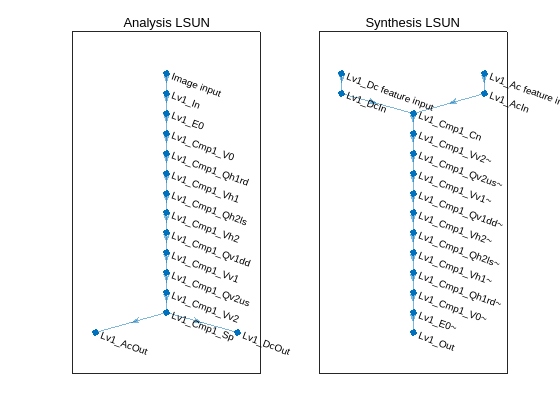

x = rand([szy szx 1 szt],'single');
dlx = dlarray(x,'SSCB');

[dls{1:2}] = analysisnet.predict(dlx);
dly = synthesisnet.predict(dls{:});
display("MSE: " + num2str(mse(dlx,dly)))

## Parameter optimization and approximation

import tansacnet.lsun.*
analysislgraph = layerGraph(analysisnet);

% Coefficient masking
nChsTotal = prod(stride);
coefMask = reshape([ones(nCoefs,1); zeros(nChsTotal-nCoefs,1)],2,[]).';
coefMask = coefMask(:);
%nLevels = 1;
%for iLv = nLevels:-1:1
iLv = 1;
strLv = sprintf('Lv%0d_',iLv);
% For AC
analysislgraph = analysislgraph.replaceLayer([strLv 'AcOut'],...

Copy angles from Lv1_Cmp1_V0 to Lv1_Cmp1_V0~
Copy angles from Lv1_Cmp1_Vh1 to Lv1_Cmp1_Vh1~
Copy angles from Lv1_Cmp1_Vh2 to Lv1_Cmp1_Vh2~
Copy angles from Lv1_Cmp1_Vv1 to Lv1_Cmp1_Vv1~
Copy angles from Lv1_Cmp1_Vv2 to Lv1_Cmp1_Vv2~


    maskLayer('Name',[strLv 'AcMask'],'Mask',coefMask(2:end),...
    'NumberOfChannels',nChsTotal-1));
%strLvPre = strLv;
%end

% Output layer
iCmp = 1;
strCmp = sprintf('Cmp%0d_',iCmp);
%analysislgraph = analysislgraph.addLayers([...
%      lsunChannelConcatenation1dLayer('Name',[strLv strCmp 'Cn']) ...
%      lsunRegressionLayer('Coefficient output')
%     ]);
analysislgraph = analysislgraph.addLayers(...
      lsunChannelConcatenation2dLayer('Name',[strLv strCmp 'Cn']));
analysislgraph = analysislgraph.connectLayers(...
    [strLv 'AcMask' ], [strLv strCmp 'Cn/ac']);
analysislgraph = analysislgraph.connectLayers(...
    [strLv 'DcOut' ], [strLv strCmp 'Cn/dc']);

figure
plot(analysislgraph)
title('Analysis LSUN')

### Reads numerical sequence data as a 2-D image from a datastore

% Please change the path
Datasetfolder ='./Experience1/Dataset';
files = dir(fullfile(Datasetfolder,'*.mat'));
data = load(fullfile(Datasetfolder,files(1).name));
u = data.u;

[V, H, T] = size(u);

% Load sequences
ds = arrayDatastore(u,"ReadSize",1,"IterationDimension",3);
arr = transform(ds,@(x) cell2mat(x));
% patchds = randomPatchExtractionDatastore(arrds,arrds,[nY nX],'PatchesPerImage',1);
% 
% figure
% minibatch = preview(patchds);
% inputimg = minibatch.InputImage;
% imshow(preview(imds));

preparation 

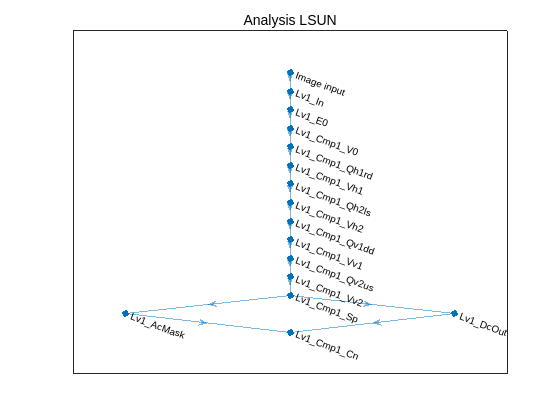

if canUseGPU
    dlX = dlarray(gpuArray(read(arr)),'SSBC');
else
    dlX = dlarray(read(arr),'SSBC');
end


trainnet = dlnetwork(analysislgraph,dlX);
assert(trainnet.Initialized)
figure
monitor = trainingProgressMonitor(Metrics="Loss",Info="Epoch",XLabel="Iteration");
% lineLossTrain = animatedline('Color',[0.85 0.325 0.098]);
% ylim([0 inf])
% xlabel("Iteration")
% ylabel("Loss")
% grid on

### Optimization settings(Adam)

Parameters for learning

- [深層学習用のミニバッチの作成 - MATLAB - MathWorks 日本](https://jp.mathworks.com/help/deeplearning/ref/minibatchqueue.html)

- miniBatchSize = length(files);

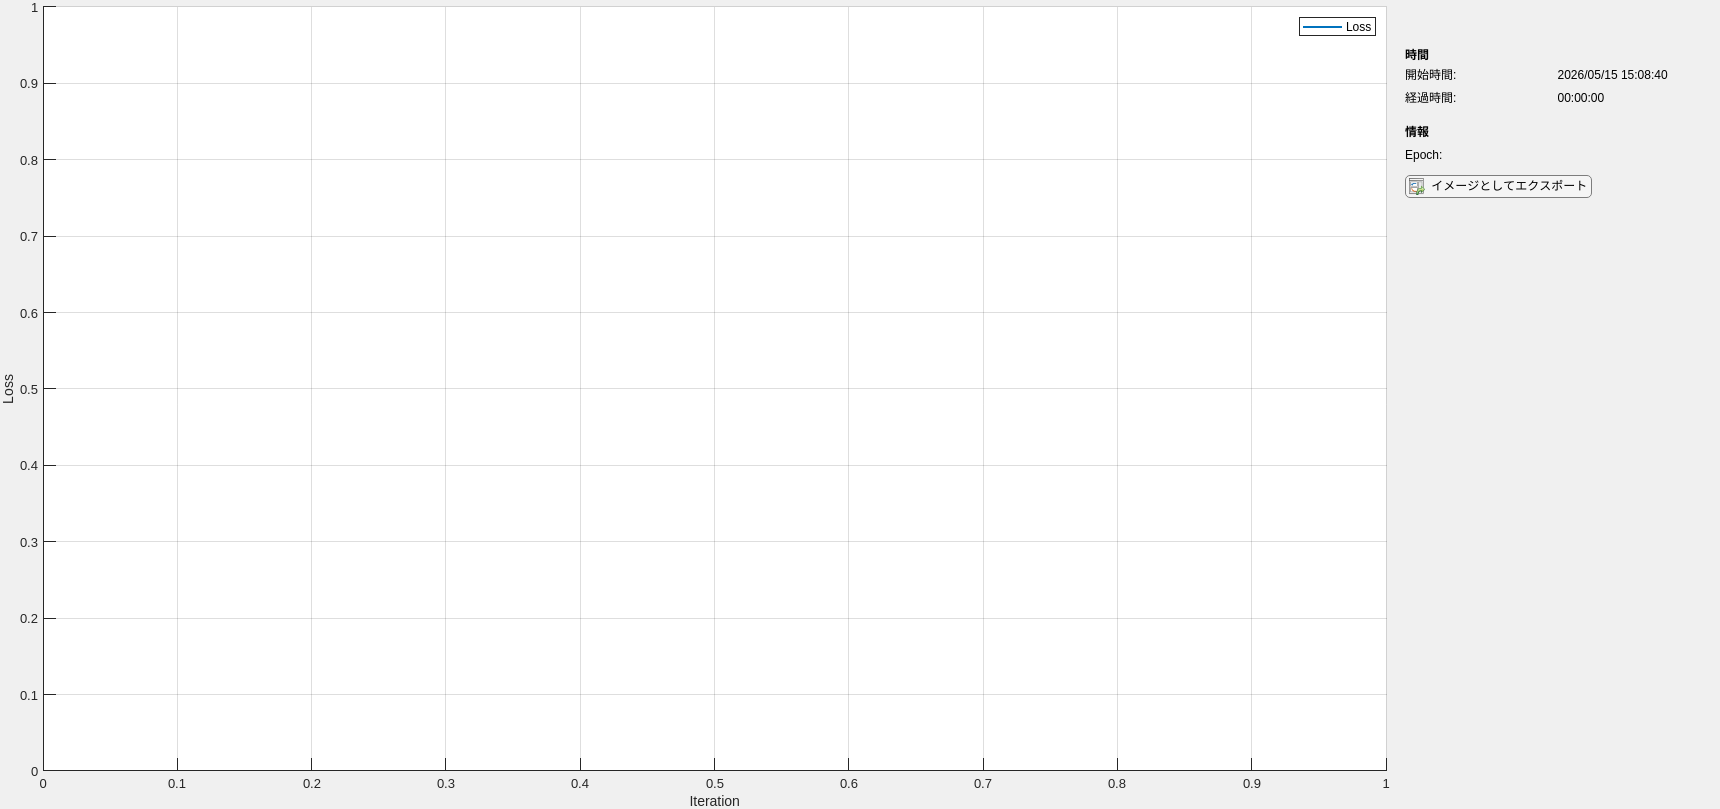

miniBatchSize = T;
numObservationsTrain = T;
numIterationsPerEpoch = ceil(numObservationsTrain / miniBatchSize);
numIterations = maxEpochs * numIterationsPerEpoch;
loss = zeros(numIterations,1);

mbq = minibatchqueue(ds,...
    "MinibatchSize",miniBatchSize,...
    ..."MiniBatchFcn",@(x) permute(x,[1 2 4 3]),...
    "OutputAsDlarray",1,...
    ..."OutputCast","double",...
    "MiniBatchFormat", "SSBC",...
    "OutputEnvironment", "gpu",...
    ..."OutputEnvironment", "cpu",...
    "PartialMiniBatch","return");

% Training
averageGrad = [];
averageSqGrad = [];
B1 = 0.9;

B2 = 0.999;
iteration = 0;
learnRate = 1e-2;
epoch = 0;
start = tic;

% Loop over epochs.
while epoch < maxEpochs && ~monitor.Stop
    epoch = epoch + 1;
    % Shuffle data.
    shuffle(mbq);

    % Loop over mini-batches.
    while hasdata(mbq) && ~monitor.Stop % hasdata(mbq)
        iteration = iteration + 1;

        % Read mini-batch of data.
        dlX = next(mbq);
        
        % Evaluate the model gradients, state, and loss using dlfeval and the
        % modelGradients function and update the network state.
        [gradients,n_loss] = dlfeval(@modelGradients,trainnet,dlX);
       
        % Update the network parameters using the SGDM optimizer.
        [trainnet,averageGrad,averageSqGrad] = adamupdate(trainnet,gradients,averageGrad,averageSqGrad,iteration,learnRate,B1,B2);
        
        % Display the training progress.
        %D = duration(0,0,toc(start),'Format','hh:mm:ss');
        %addpoints(lineLossTrain,iteration,loss)
        %title("Epoch: " + epoch + ", Elapsed: " + string(D))
        %drawnow
        recordMetrics(monitor,iteration,Loss=n_loss);
        updateInfo(monitor,Epoch=epoch + " of " + maxEpochs);
        monitor.Progress = 100 * iteration/numIterations;
        loss(iteration,1) = n_loss;
    end
    
    reset(mbq);
end

## Approximation by LSUN-base linear autoencoder 

import tansacnet.lsun.*
lsunlgraph = fcn_createlsunlgraph2d([],...
    'InputSize',[szy szx],...
    'Stride',stride,...
    'OverlappingFactor',ovlpFactor,...
    'NumberOfVanishingMoments',noDcLeakage,...
    'Mode','Whole');
trainlgraph = layerGraph(trainnet);
lsunlgraph = fcn_cpparamsana2syn(lsunlgraph,trainlgraph);

Copy angles from Lv1_Cmp1_V0 to Lv1_Cmp1_V0~
Copy angles from Lv1_Cmp1_Vh1 to Lv1_Cmp1_Vh1~
Copy angles from Lv1_Cmp1_Vh2 to Lv1_Cmp1_Vh2~
Copy angles from Lv1_Cmp1_Vv1 to Lv1_Cmp1_Vv1~
Copy angles from Lv1_Cmp1_Vv2 to Lv1_Cmp1_Vv2~


%lsunlgraph = fcn_cpparamsana2syn_csax_(lsunlgraph,trainlgraph); 
lsunlgraph = fcn_cpparamssyn2ana(lsunlgraph,lsunlgraph);

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2


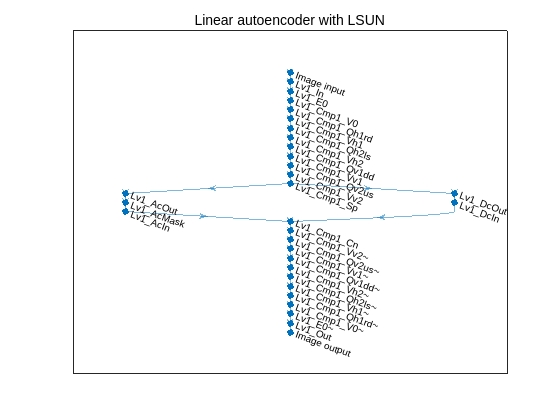

%lsunlgraph = fcn_cpparamssyn2ana_csax_(lsunlgraph,lsunlgraph); 

%nLevels = 1;
%for iLv = nLevels:-1:1S
iLv = 1;
strLv = sprintf('Lv%0d_',iLv);
lsunlgraph = lsunlgraph.disconnectLayers([strLv 'AcOut'],[strLv 'AcIn']);
% For AC
lsunlgraph = lsunlgraph.addLayers(...
    maskLayer('Name',[strLv 'AcMask'],'Mask',coefMask(2:end),...
    'NumberOfChannels',nChsTotal-1));
lsunlgraph = lsunlgraph.connectLayers([strLv 'AcOut'],[strLv 'AcMask']);
lsunlgraph = lsunlgraph.connectLayers([strLv 'AcMask'],[strLv 'AcIn']);
%strLvPre = strLv;
%end
%

figure
plot(lsunlgraph)
title('Linear autoencoder with LSUN')

### Approximation

lsunnet = assembleNetwork(lsunlgraph);
u_reconstruct = zeros(size(u),'like',u);
for iT = 1:szt
    u_reconstruct(:,:,iT) = lsunnet.predict(gpuArray(u(:,:,iT)));
end

### Evaluation and Save Results

mse = mean((u - u_reconstruct).^2,'all')
mae = mean(abs(u - u_reconstruct),'all')

pass = "./Experience1/Result/batchLSUN/K_2/";
%% Save WorkSpace
writematrix(mse,pass + "mse.txt");
writematrix(mae,pass + "mae.txt");
writematrix(n_loss,pass + "loss.txt");

save(pass + "u_reconstruct.mat","u_reconstruct");
save(pass + "loss.mat","loss");
angle = trainnet.Learnables.Value;
save(pass + "parameter.mat","angle");

## Definitions of local functions

Loss function

    $L(\mathbf{\theta}) = \|\mathbf{x}\|_2^2-\|F_\mathbf{\theta}(\mathbf{x})\|_2^2$,

where $F_\mathbf{\theta}(\cdot)$ is a unitary analyzer with a coefficient mask. $L(\mathbf{\theta})\geq 0$ is guaranteed.

function [gradients, loss] = modelGradients(dlnet, dlX)
% Forward data through the dlnetwork object.
dlY = forward(dlnet,dlX); % F(x)
% Compute loss.
Nx = size(dlX,4);
Ny = size(dlY,4);
loss = sum(dlX.^2,"all")/Nx-sum(dlY.^2,"all")/Ny;
% Compute gradients.
gradients = dlgradient(loss,dlnet.Learnables);
loss = double(gather(extractdata(loss)));
end